# Solution to *UAV Capabilities I *exercise

The file `UAVData.xlsx` contains four columns of data on 33 unmanned aerial vehicles (UAVs). The first column contains the names of the UAVs; the next three columns contain numeric data: endurance (hours), payload (pounds), and operational altitude ceiling (feet), respectively.

## 1. Import data as table

UAV = readtable('UAVData.xlsx');

## 2. Calculate total load capacity

UAV.LoadCap = UAV.Endurance.*UAV.PayloadWeight;

## 3. Sort table by load capacity

byCapacity = sortrows(UAV,'LoadCap','descend');

disp('UAVs in order of total load capacity:')

UAVs in order of total load capacity:


disp(byCapacity.UnmannedAerialVehicle)

    'Theseus'
    'Perseus B'
    'Predator'
    'Darkstar'
    'Chiron'
    'Model 410'
    'Eagle Eye'
    'Hunter'
    'Skyeye'
    'Pathfinder'
    'Shadow 600'
    'Outrider'
    'Huntair'
    'Raptor'
    'Firebee'
    'Spectre II'
    'Model 324'
    'SASS Lite'
    'STM-5B'
    'Model 350'
    'Porter'
    'Prowler'
    'Truck'
    'Freewing'
    'Seabat'
    'Cypher'
    'Tern'
    'Hawk-i 7F'
    'Javelin'
    'Hawk-i 7H'
    'AV Pointer Micro Blimp'
    'Hawk-i 7B'
    'AV Pointer'



## 4. Create histogram

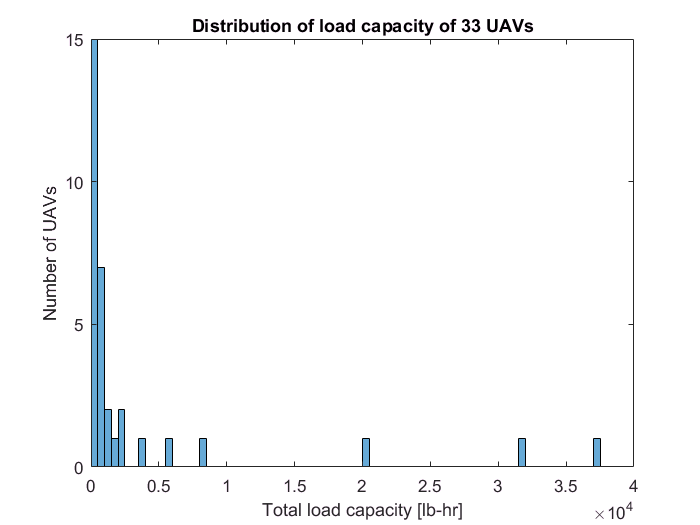

histogram(UAV.LoadCap,'BinWidth',500)
xlabel('Total load capacity [lb-hr]')
ylabel('Number of UAVs')
title('Distribution of load capacity of 33 UAVs')